**P.10**

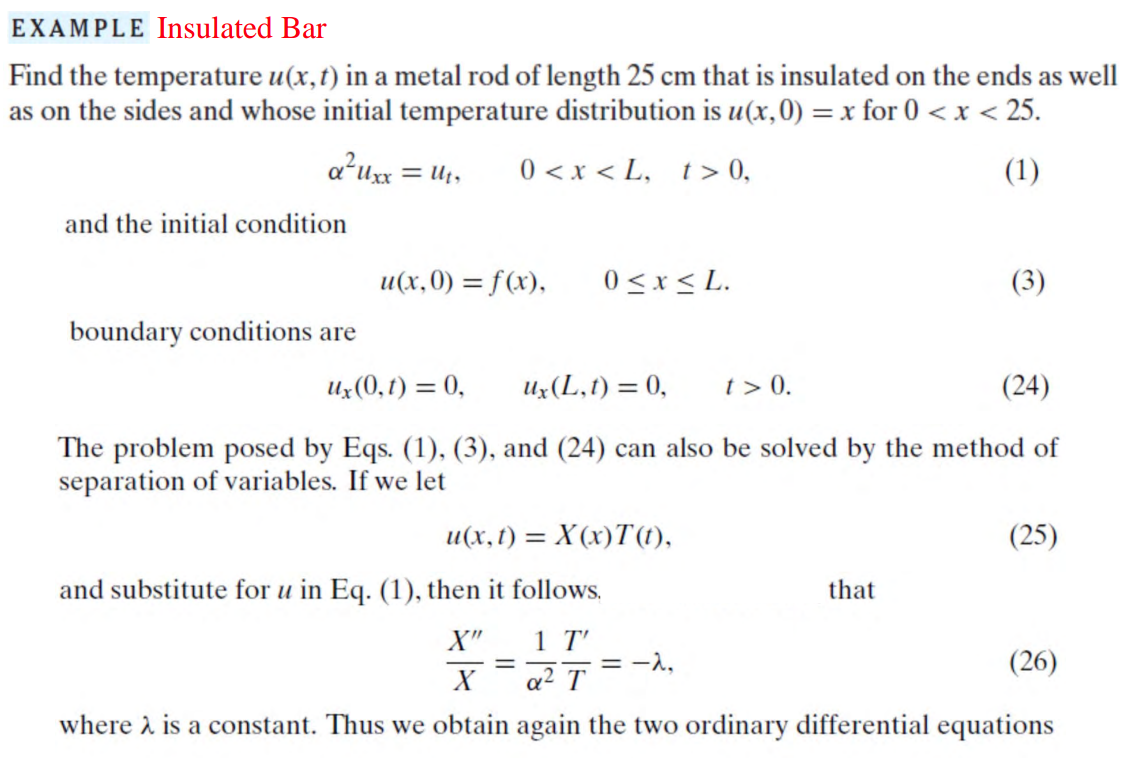

clear
clf
clc
syms x t u(x,t) L D
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

Dx = diff(u,x)

$$Dx(x, t) = \frac{\partial }{\partial x}u\left(x,t\right)$$

BC0 = Dx(0,t) == 0

$$BC0 = \left({\left(\frac{\partial }{\partial x}u\left(x,t\right)\right)|}_{x=0}\right)=0$$

BCL = Dx(L,t) == 0

$$BCL = \frac{\partial }{\partial L}u\left(L,t\right)=0$$

**Substitution**

syms T(t) X(x)
SepVar = subs(HeatEq, u(x,t), X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=\text{D}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$

SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

**Separate ODEs introduce constant (Lambda)^2**

var = children(SepVar);

**Separation**

syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX)

$$X(x, lambda) = C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)$$

Dx(x,lambda) = diff(X,x)

$$Dx(x, lambda) = -C_{2}\,\lambda \,\cos\left(\lambda \,x\right)-C_{1}\,\lambda \,\sin\left(\lambda \,x\right)$$

disp(-Dx(0,1) == 0)

$$C_{2}=0$$

var = children(X);
xL(x,lambda) = cell2sym(var(1))

$$xL(x, lambda) = C_{1}\,\cos\left(\lambda \,x\right)$$

DxL(x,lambda) = diff(xL,x)

$$DxL(x, lambda) = -C_{1}\,\lambda \,\sin\left(\lambda \,x\right)$$

sln = DxL(L,lambda) == 0;

**Solve for lambda**

[lambda,parameter,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameter,n)

$$lambda = \frac{\pi \,n}{L}$$

syms a_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(xL(x,lambda),[lambda,sym('C1')],[lambda,a_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["cos" "exp"])

$$ustruct(x, t, n) = a_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\cos\left(\frac{\pi \,n\,x}{L}\right)$$

**Fourier series part**

syms x t n a(n) phi(x)
assume(n,"integer")
L = 25

L = 25

phi(x) = x;
D = 1

D = 1

N = 20

N = 20

ft0 = subs(ustruct(x,0,n),sym(["a_n" "L"]),[1 L])

$$ft0 = \cos\left(\frac{\pi \,n\,x}{25}\right)$$

a0 = simplify(2/L*int(phi(x),x,[0 L]))

$$a0 = 25$$

a(n) = simplify(2/L*int(phi(x)*ft0,x,[0 L]))

$$a(n) = -\frac{25\,{\left(-1\right)}^{n+1}\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{n^{2}\,\pi^{2}}$$

heatStruct = ustruct

$$heatStruct(x, t, n) = a_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\cos\left(\frac{\pi \,n\,x}{L}\right)$$

heatstructEmb(x,t,n) = subs(heatStruct,sym(["a_n" "L" "D"]),[a L D]);

**Heat Solution**

Solution = symsum(heatstructEmb,n,1,inf)

$$Solution(x, t) = -\frac{25\,\left(\sum_{n=1}^{\infty }\frac{{\left(-1\right)}^{n+1}\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{625}}\,\cos\left(\frac{\pi \,n\,x}{25}\right)\,{\left({\left(-1\right)}^{n}-1\right)}^{2}}{n^{2}}\right)}{\pi^{2}}$$

heatSolN = a0/2+simplify(symsum(heatstructEmb,n,1,N))

$$heatSolN(x, t) = \begin{array}{l} \frac{25}{2}-\frac{33870234994596\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{25}}\,\cos\left(\frac{\pi \,x}{5}\right)+3763359443844\,{\mathrm{e}}^{-\frac{\sigma_{1}}{25}}\,\cos\left(\frac{3\,\pi \,x}{5}\right)+846755874864900\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{625}}\,\cos\left(\frac{\pi \,x}{25}\right)+94083986096100\,{\mathrm{e}}^{-\frac{\sigma_{1}}{625}}\,\cos\left(\frac{3\,\pi \,x}{25}\right)+17280732140100\,{\mathrm{e}}^{-\frac{49\,t\,\pi^{2}}{625}}\,\cos\left(\frac{7\,\pi \,x}{25}\right)+10453776232900\,{\mathrm{e}}^{-\frac{81\,t\,\pi^{2}}{625}}\,\cos\left(\frac{9\,\pi \,x}{25}\right)+6997982436900\,{\mathrm{e}}^{-\frac{121\,t\,\pi^{2}}{625}}\,\cos\left(\frac{11\,\pi \,x}{25}\right)+5010389792100\,{\mathrm{e}}^{-\frac{169\,t\,\pi^{2}}{625}}\,\cos\left(\frac{13\,\pi \,x}{25}\right)+2929951124100\,{\mathrm{e}}^{-\frac{289\,t\,\pi^{2}}{625}}\,\cos\left(\frac{17\,\pi \,x}{25}\right)+2345584140900\,{\mathrm{e}}^{-\frac{361\,t\,\pi^{2}}{625}}\,\cos\left(\frac{19\,\pi \,x}{25}\right)}{8467558748649\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=9\,t\,\pi^{2} \end{array}$$

**3D plot**

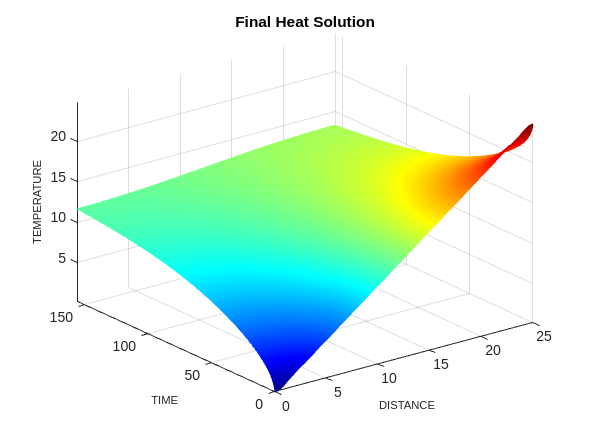

figure
colormap jet
tau = L^2/D;
fsurf(heatSolN,[0 L 0 tau/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','Fontsize',8);
ylabel('TIME','Fontsize',8);
zlabel('TEMPERATURE','Fontsize',8)

**Heat profile at different times**

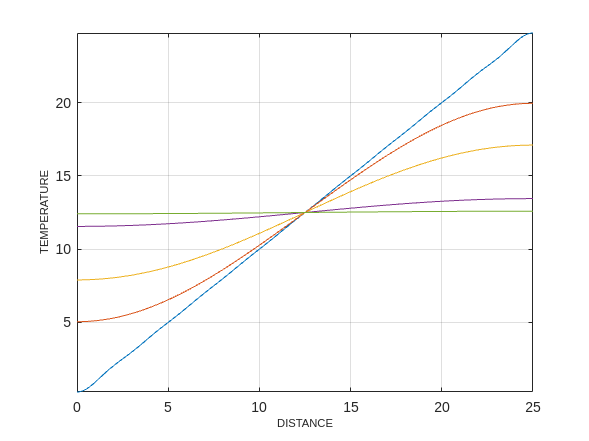

clf
tm = [0 20 50 150 300];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn, [0 L])
    grid on, hold on
end 
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','Fontsize',8)

**P.19**

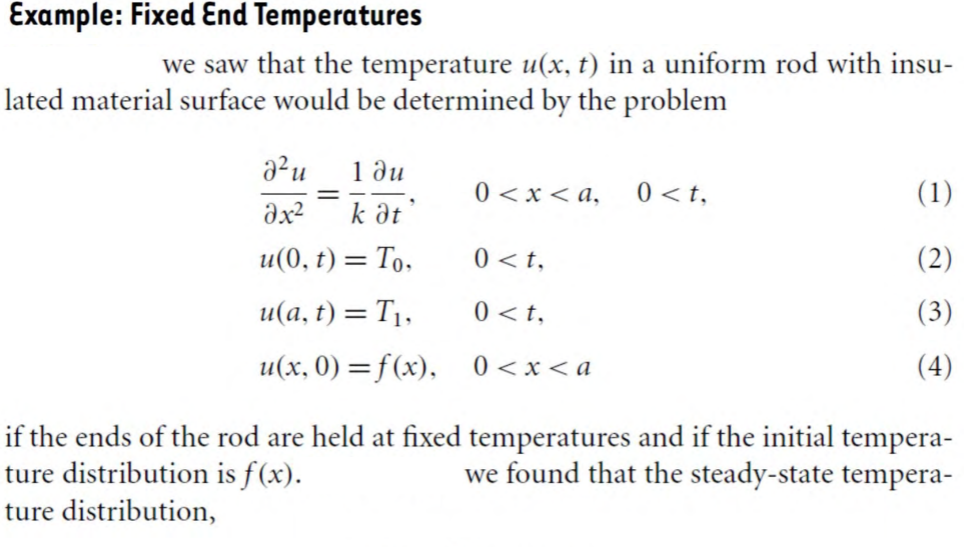

**Steady state v(x)**

clear
clf
clc
syms x v(x) a T0 T1 D;
assume(a,"positive")
SteadyS = D*diff(v,x,2) == 0

$$SteadyS(x) = \text{D}\,\frac{\partial^{2}}{\partial x^{2}}v\left(x\right)=0$$

c0 = v(0) == T0

$$c0 = v\left(0\right)=T_{0}$$

ca = v(a) == T1

$$ca = v\left(a\right)=T_{1}$$

v(x) = dsolve(SteadyS,[c0 ca])

$$v(x) = T_{0}-\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

**Transient w(x,t) = u(x,t) -v(x)**

**Separaton part**

syms t w(x,t)
assume([a D],"positive")
HeatEq = diff(w,t) == D*diff(w,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}w\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}w\left(x,t\right)$$

BC0 = w(0,t) == 0

$$BC0 = w\left(0,t\right)=0$$

BCL = w(a,t) == 0

$$BCL = w\left(a,t\right)=0$$


syms T(t) X(x)
SepVar = subs(HeatEq,w(x,t),X(x)*T(t));
SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children(SepVar);
BCx0 = subs(BC0,w(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

BCxa = subs(BCL,w(a,t),X(a))

$$BCxa = X\left(a\right)=0$$

**Separation**

syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['c',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

**Finding lambda**

sln = X(a,lambda) == 0;
[lambda,parameters,condition] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin","exp"])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

**Fourier series part **

syms x t n b(n) phi(x)
assume(n,"integer")
phi(x) = 0 -v(x);
ft0 = subs(ustruct(x,0,n),sym("b_n"),1)

$$ft0 = \sin\left(\frac{\pi \,n\,x}{a}\right)$$

b(n) = simplify(2/a*int(phi(x)*ft0,x,[0 a]))

$$b(n) = -\frac{2\,\left(T_{0}-{\left(-1\right)}^{n}\,T_{1}\right)}{n\,\pi }$$

D = 0.10

D = 0.1000

N = 1

N = 1

T0 = 20

T0 = 20

T1 = 100

T1 = 100

a = 1

a = 1

tau = 6

tau = 6

v(x) = subs(v,sym(["a" "T0" "T1"]),[a T0 T1])

$$v(x) = 80\,x+20$$

b(n) = subs(b,sym(["T0" "T1"]),[T0 T1])

$$b(n) = \frac{2\,\left(100\,{\left(-1\right)}^{n}-20\right)}{n\,\pi }$$

heatStruct = ustruct 

$$heatStruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)$$

heatStruct(x,t,n) = subs(heatStruct,sym(["b_n" "a" "D"]),[b a D]);

**Solution**

heatSolN = v(x)+simplify(symsum(heatStruct,n,1,N))

$$heatSolN(x, t) = 80\,x-\frac{240\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{10}}\,\sin\left(\pi \,x\right)}{\pi }+20$$

heatstructEmb(x,t,n) = v(x)+symsum(heatStruct,n,1,inf)

$$heatstructEmb(x, t, n) = 80\,x+\frac{2\,\left(\sum_{n=1}^{\infty }\frac{\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{10}}\,\left(100\,{\left(-1\right)}^{n}-20\right)}{n}\right)}{\pi }+20$$

**3D plot**

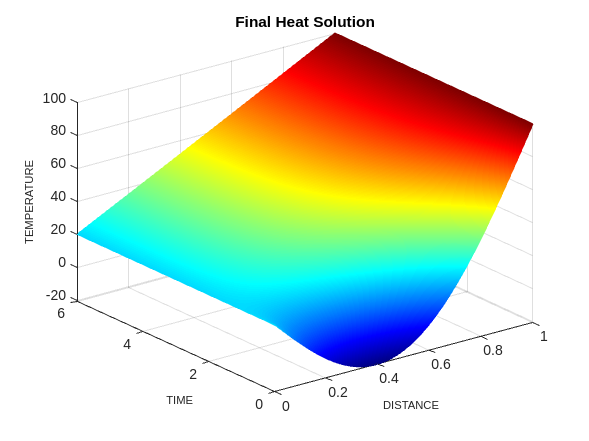

figure
colormap jet
fsurf(heatSolN,[0 a 0 tau],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8);
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)

**Heat profile at different times**

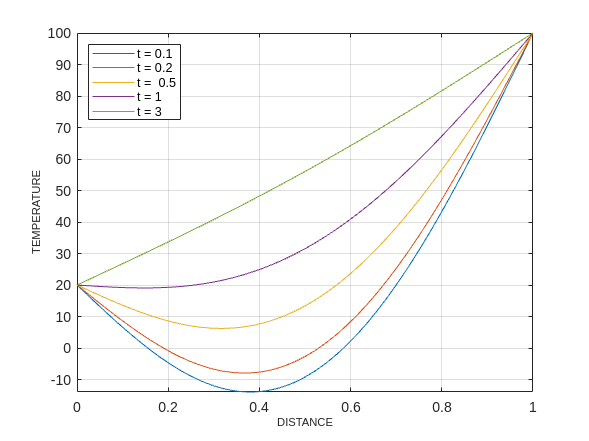

clf
tm = [0.1 0.2 0.5 1 3];
for i = 1:length(tm)
    sn  = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn,[0 a])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('t = 0.1','t = 0.2','t =  0.5','t = 1','t = 3','Location','northwest')

**Heat profile at various times**

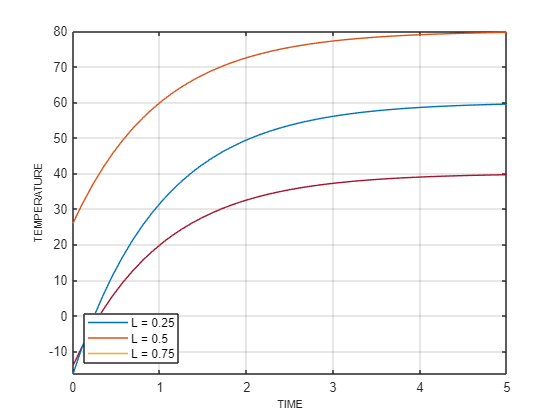

clf
dst = [0.25 0.5 0.75];
for i = 1:length(dst)
    sn  = matlabFunction(heatSolN(dst,t));
    fplot(sn,[0 5])
    grid on, hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('L = 0.25','L = 0.5','L = 0.75','Location','southwest')

**P.43**

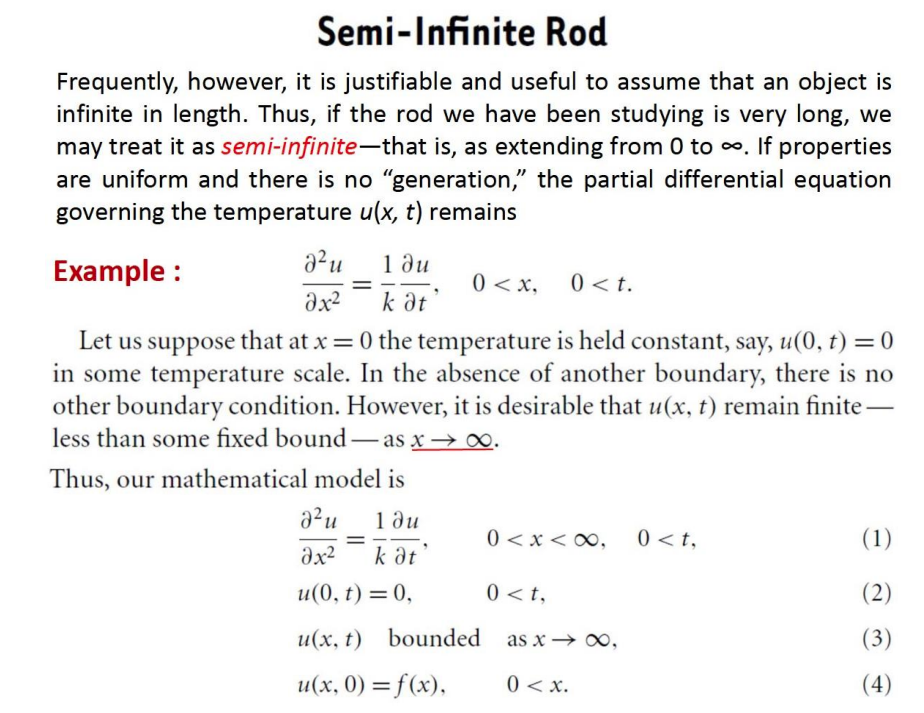

**Separation part**

clear
clc
syms x t u(x,t) L D h
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;
syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

syms b_n ustrcut(x,t,n);
expT(t,lambda) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,lambda) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t) = collect(sinX(x,lambda)*expT(t,lambda),["sin" "exp"])

$$ustruct(x, t) = b_{n}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

Fourier integral part

syms x t b(lambda) phi(x)
L = inf;
phi(x) = x;
D = 1

D = 1

ft0 = subs(ustruct(x,0),sym(["b_n" "L" "lambda"]),[1 L lambda])

$$ft0 = \sin\left(\lambda \,x\right)$$

b(lambda) = simplify(2/pi*int(ft0,x,[0 L]))

$$b(lambda) = \frac{5734161139222659}{9007199254740992\,\lambda }-\frac{5734161139222659\,\left(\lim_{x\to \infty }\cos\left(\lambda \,x\right)\right)}{9007199254740992\,\lambda }$$

heatstructEmb(x,t,lambda) = subs(ustruct,sym(["b_n" "L" "D"]),[b L D])

$$heatstructEmb(x, t, lambda) = -{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)\,\left(\frac{5734161139222659\,\left(\lim_{x\to \infty }\cos\left(\lambda \,x\right)\right)}{9007199254740992\,\lambda }-\frac{5734161139222659}{9007199254740992\,\lambda }\right)$$